## **Driver test program to check Clothoids library**

**Biarcs**

Compare biarc of the Clothoids library with the MATLAB biarc of function fnrfn.

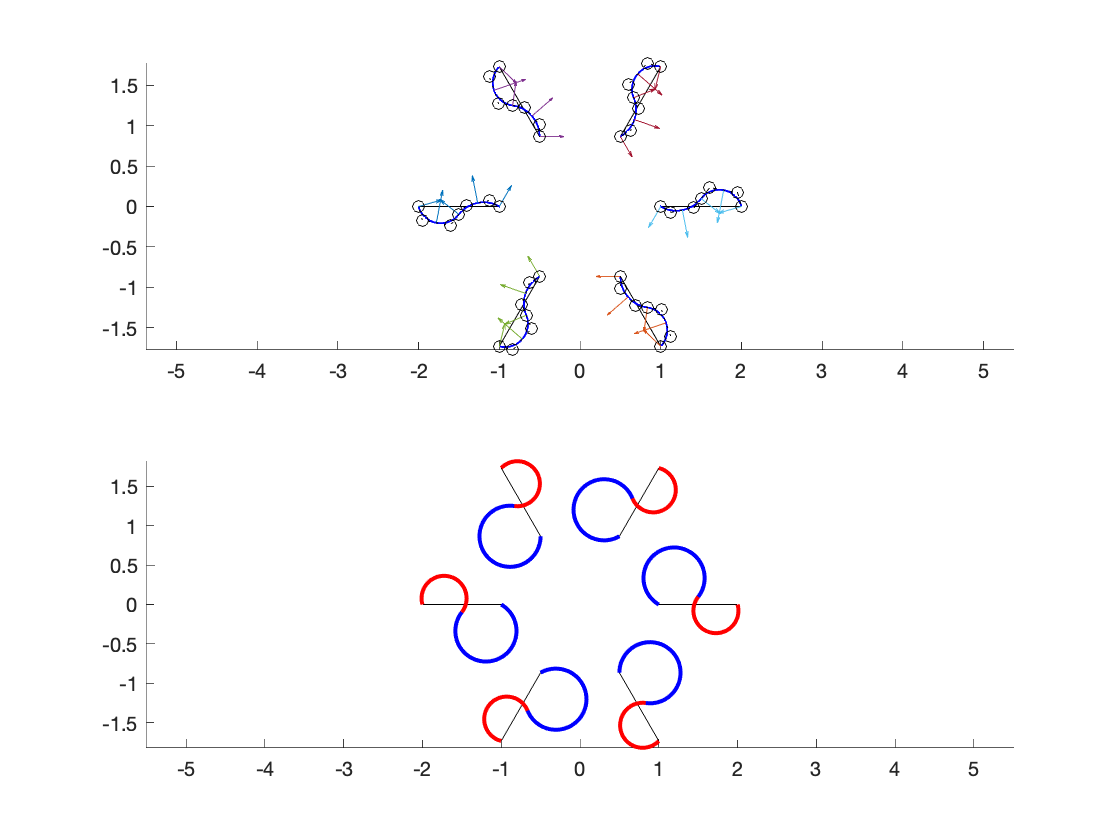

subplot(2,1,1);
hold off
hold on

subplot(2,1,2);
hold off
hold on

for a=0:pi/3:2*pi

  x0=cos(a);
  y0=sin(a);
  x1=2*cos(a);
  y1=2*sin(a);

  theta0=pi/1.2;
  theta1=pi/1.7;

  a0=theta0+pi/2+a;
  a1=theta1+pi/2+a;
  
  p=[x0,x1;y0,y1];
  u=[cos(a0),cos(a1);sin(a0),sin(a1)];

  subplot(2,1,1);
  plot(p(1,:),p(2,:),'k')
  bi_arc = fnrfn(rscvn(p,u),[0.5,1.5]);
  bspline_plot(bi_arc,true);

  subplot(2,1,2);
  plot(p(1,:),p(2,:),'k')
  L1 = Biarc( x0, y0, theta0+a, x1, y1, theta1+a );
  L1.plot();
end

subplot(2,1,1);
axis equal

subplot(2,1,2);
axis equal